# 数据处理与分析

## 表 1

A = [
-0.1	0.0	0.1	-0.1
25.7	-25.7	26.1	-25.7
51.4	-51.5	52.2	-52.2
77.1	-77.1	78.2	-78.3
102.7	-102.7	104.2	-104.2
128.7	-128-7	130.6	-130.7
154.5	-154.5	156.6	-156.7
];
A = abs(A);
mean(A, 2);
PrintData(mean(A, 2));

I_S = 0:0.5:3;
V_H = A(:, end);
[fun, out] = LinearFit(I_S, V_H);
stc = MyFitPlot(fun, I_S, V_H');
stc.label.x.String = '$I_S$ (mA)';
stc.label.y.String = '$V_H$ (mV)';
stc.ax.Title.String = ['$R^2 = $', num2str(out.rsquare, '%.7f'), ', SSE = ', num2str(out.sse, '%.5f'), ', RMSE = ',  num2str(out.rmse, '%.5f')];

disp(['R^2  = ', num2str(out.rsquare, '%.7f')])
disp(['SSE  = ', num2str(out.sse, '%.5f')])
disp(['RMSE = ', num2str(out.rmse, '%.5f')])
%MyExport_pdf_docked

## 表 2

A = [
-0.3	0.3	0.4	-0.4
12.4	-12.4	13.1	-13.1
25.2	-25.2	26.2	-26.2
38.3	-38.4	39.1	-39.1
51.0	-51.0	51.9	-51.9
64.0	-64.0	64.8	-64.8
76.9	-76.9	77.7	-77.8
];
A = abs(A);
mean(A, 2);
PrintData(mean(A, 2))

I_M = 0:50:300;
V_H = A(:, end);

I_M = 0:50:300;
[fun, out] = LinearFit(V_H, B);
stc = MyFitPlot(fun, V_H', B');
stc.label.x.String = '$I_S$ (mA)';
stc.label.y.String = '$V_H$ (mV)';
stc.ax.Title.String = ['$R^2 = $', num2str(out.rsquare, '%.7f'), ', SSE = ', num2str(out.sse, '%.5f'), ', RMSE = ',  num2str(out.rmse, '%.5f')];

disp(['R^2  = ', num2str(out.rsquare, '%.7f')])
disp(['SSE  = ', num2str(out.sse, '%.5f')])
disp(['RMSE = ', num2str(out.rmse, '%.5f')])

%MyExport_pdf

k = 2.75
K_H_ex = 1/(1e-3*k)
K_H = 371;
GetEta(K_H, K_H_ex)
R = out.rsquare
n = 7
sigma = K_H_ex * sqrt( (1 - R^2) / ((n-2)*R^2) )


## 表 3

A = [
0.0	0.0	0.0	0.0
35.2	35.2	-35.6	-35.5
70.6	70.6	-71.2	-71.2
106.5	106.5	-106.6	-106.6
141.7	141.6	-141.5	-141.5
177.7	177.7	-177.1	-177.1
213.4	213.5	-213.3	-213.3
];
A = abs(A);
mean(A, 2);
PrintData(mean(A, 2));

I_M = 0:50:300;
B = A(:, end);

I_M = 0:50:300;
[fun, out] = LinearFit(B, I_M);
stc = MyFitPlot(fun, B', I_M);
stc.label.x.String = '$B$ (mT)';
stc.label.y.String = '$I_M$ (mA)';
stc.ax.Title.String = ['$R^2 = $', num2str(out.rsquare, '%.7f'), ', SSE = ', num2str(out.sse, '%.5f'), ', RMSE = ',  num2str(out.rmse, '%.5f')];

disp(['R^2  = ', num2str(out.rsquare, '%.7f')])
disp(['SSE  = ', num2str(out.sse, '%.5f')])
disp(['RMSE = ', num2str(out.rmse, '%.5f')])

%MyExport_pdf

## 表 4

X = [42	40	38	36	34	32	30 28	26	24	22	20	18	16	14
];
B = [143.2	143.3	143.2	143.1	143.1	143.1	143.1   143.1	143.1	143.1	143.1	143.1	143.1	143.1	143.0
];

stc = MyPlot(X, B);
stc.label.x.String = '$X$ (mm)';
stc.label.y.String = '$B$ (mT)';

%MyExport_pdf_docked

## 表 5

I_M = 50:25:200;
B = [34.9	52.6	70.5	88.4	106.1	124.0	141.4
];

[fun, out] = LinearFit(I_M, B);
stc = MyFitPlot(fun, I_M, B);
stc.label.x.String = '$I_M$ (mA)';
stc.label.y.String = '$B$ (mT)';
stc.ax.Title.String = ['$R^2 = $', num2str(out.rsquare, '%.7f'), ', SSE = ', num2str(out.sse, '%.5f'), ', RMSE = ',  num2str(out.rmse, '%.5f')];

disp(['R^2  = ', num2str(out.rsquare, '%.7f')])
disp(['SSE  = ', num2str(out.sse, '%.5f')])
disp(['RMSE = ', num2str(out.rmse, '%.5f')])

%MyExport_pdf_docked

## 表 6

f = 120;
X = [-25 -20 -15 -10 -5	0 5	10 15 20 25
]*10^(-3);
A = [
5.45	5.62	5.75	5.83	5.88	5.90	5.88	5.81	5.70	5.58	5.41    
];
B_ex = 2.926/f*A;
PrintData(B');

ans = 7×1 table
    data 
    _____

     34.9
     52.6
     70.5
     88.4
    106.1
      124
    141.4



% 理论值
mu_0 = 4*pi*10^(-7);
N_0 = 400;
I = 60e-3;
R = 105e-3;
B_tho = mu_0*N_0*I*R^2 ./ (2*(R^2 + X.^2).^(3/2));
PrintData(1000*B_tho');

ans = 11×1 table
     data  
    _______

    0.13222
    0.13614
    0.13933
    0.14168
    0.14313
    0.14362
    0.14313
    0.14168
    0.13933
    0.13614
    0.13222


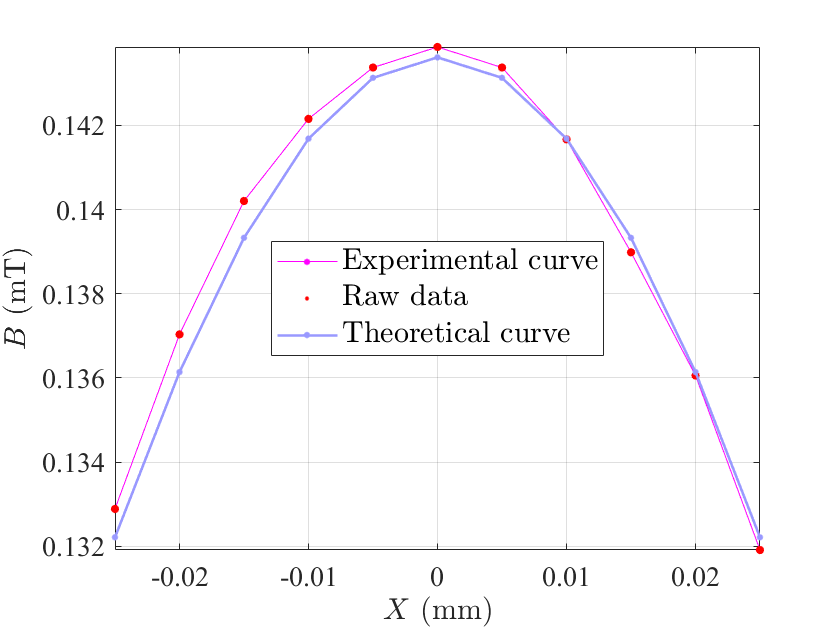


stc = MyPlot_TheoAndExpe(X, B_ex, X, B_tho*1000);
stc.label.x.String = '$X$ (mm)';
stc.label.y.String = '$B$ (mT)';

MyExport_pdf_docked

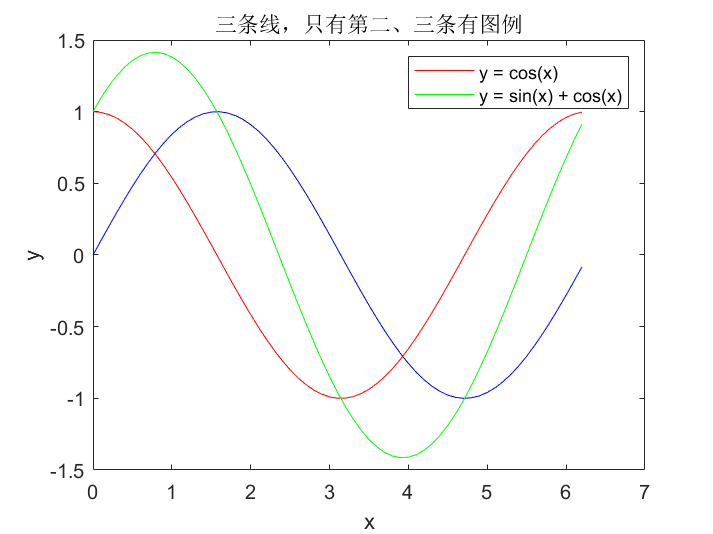

% 创建一些数据
x = 0:0.1:2*pi;
y1 = sin(x);
y2 = cos(x);
y3 = sin(x) + cos(x);

% 绘制三条线
h1 = plot(x, y1, 'b'); % 第一条线，不显示图例
hold on; % 保持当前图形，以便添加更多线条
h2 = plot(x, y2, 'r'); % 第二条线，显示图例
h3 = plot(x, y3, 'g'); % 第三条线，显示图例

% 添加图例，只显示第二条和第三条线
legend([h2 h3], {'y = cos(x)', 'y = sin(x) + cos(x)'});

% 添加轴标签
xlabel('x');
ylabel('y');

% 添加标题
title('三条线，只有第二、三条有图例');

## 表 7

Xdata = [-25	-20	-15	-10	-5	0	5	10	15	20	25
]*10^(-3);
U = [8.43	8.45	8.46	8.47	8.46	8.46	8.46	8.43	8.44	8.44	8.43
];
B = 2.926/f*U;
PrintData(B');

ans = 11×1 table
     data  
    _______

    0.20555
    0.20604
    0.20628
    0.20653
    0.20628
    0.20628
    0.20628
    0.20555
     0.2058
     0.2058
    0.20555




mu_0 = 4*pi*10^(-7);
N_0 = 400;
I = 60e-3;
R = 105e-3;
syms x a

vpa(0.5*mu_0*N_0*I*R^2)

$$ans = 0.00000016625308322797183361606613259676$$

vpa(R^2)

$$ans = 0.011025$$

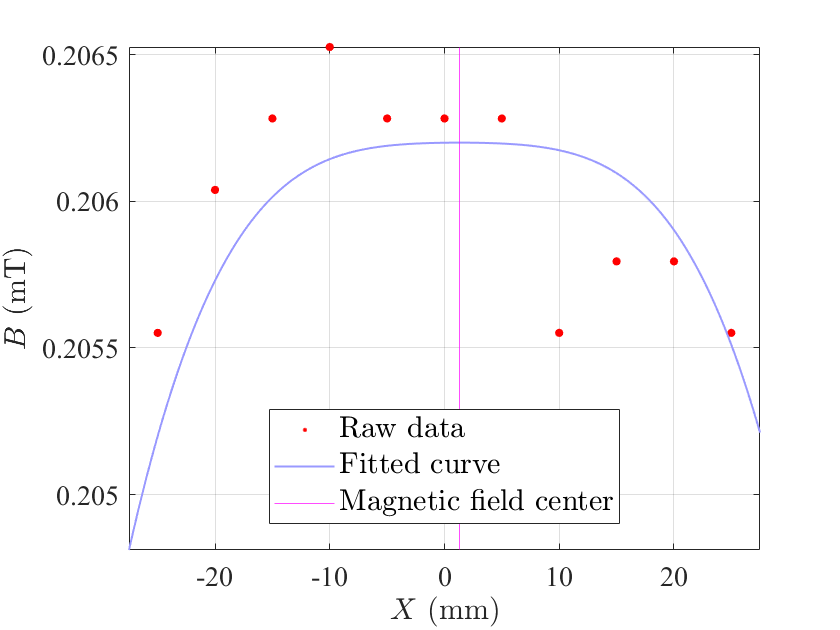


% 单位转换
B = B*10^(-3);

[fun, out] = FitHaiMuHuoZi(Xdata, B);
stc = MyPlot_FitAndRaw(@(x) fun(x/1000)*1000, Xdata*1000, B*1000);
stc.label.x.String = '$X$ (mm)';
stc.label.y.String = '$B$ (mT)';
xline(0.001295*1000, 'Color', [1 0 1]);
stc.leg.String{3} = 'Magnetic field center'; 
%MyExport_pdf_docked


GetEta(105, 104.4);

eta = -0.57143 %


## 表 8

X = [-25	-20	-15	-10	-5	0	5	10	15	20	25
]*10^(-3);
U = [8.46	8.47	8.47	8.47	8.47	8.46	8.46	8.46	8.45	8.43	8.42
];
B = 2.926/f*U;
PrintData(B');

ans = 11×1 table
     data  
    _______

    0.20628
    0.20653
    0.20653
    0.20653
    0.20653
    0.20628
    0.20628
    0.20628
    0.20604
    0.20555
    0.20531


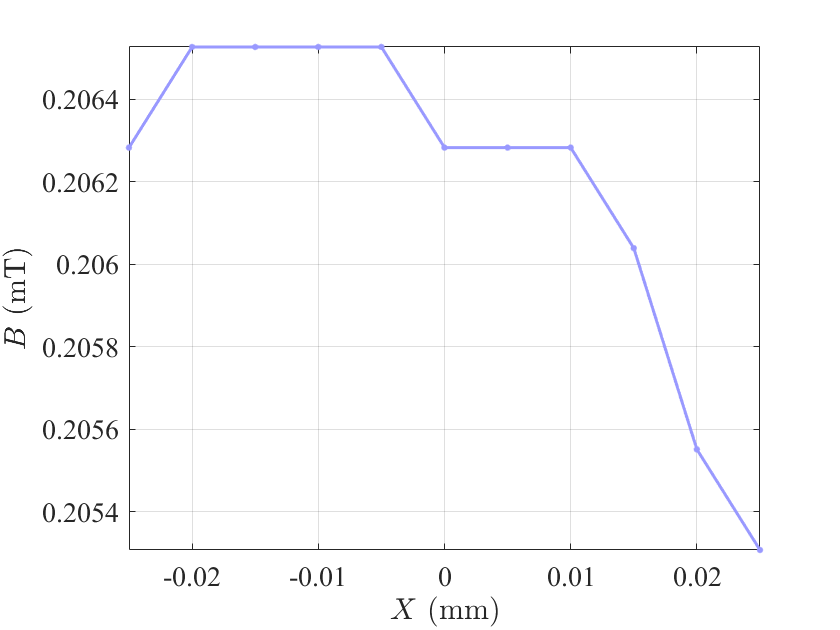


stc = MyPlot(X, B);
stc.label.x.String = '$X$ (mm)';
stc.label.y.String = '$B$ (mT)';

MyExport_pdf_docked

## 表 9

theta = 0:10:360;
U_m = 8.47;
U = abs(U_m.*cosd(theta));
PrintData(U');

ans = 37×1 table
     data 
    ______

      8.47
    8.3413
    7.9592
    7.3352
    6.4884
    5.4444
     4.235
    2.8969
    1.4708
         0
    1.4708
    2.8969
     4.235
    5.4444
    6.4884
    7.3352


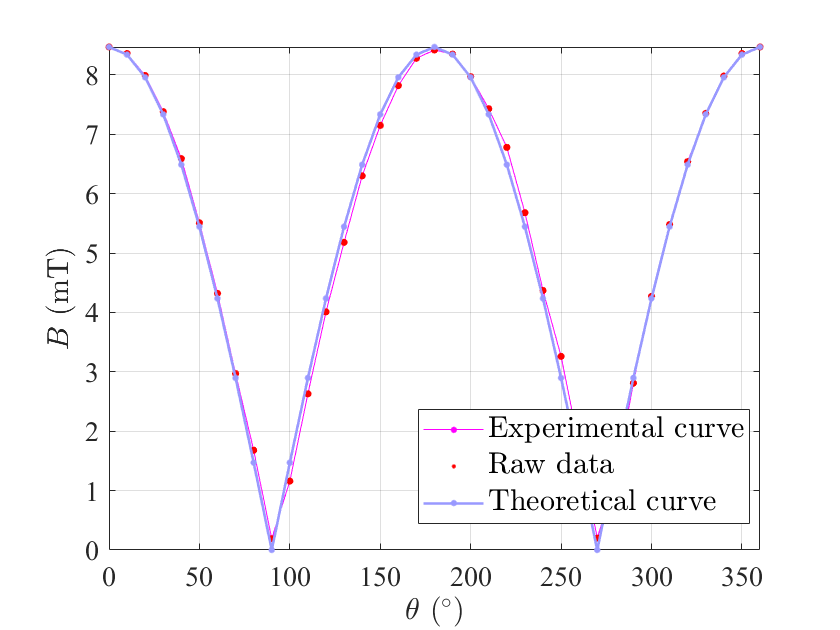


U_ex = [
8.47	8.36	7.99	7.38	6.59	5.51	4.32	2.97	1.68	0.19	1.16	2.63	4.01	5.18	6.30	7.15	7.82	8.28	8.42	8.35	7.97	7.43	6.78	5.68	4.37	3.26	1.74	0.20	1.18	2.81	4.27	5.48	6.54	7.35	7.98	8.36	8.47    
];
U_th = [      8.47	    8.3413	    7.9592	    7.3352	    6.4884	    5.4444	     4.235	    2.8969	    1.4708	         0	    1.4708	    2.8969	     4.235	    5.4444	    6.4884	    7.3352	    7.9592	    8.3413	      8.47	    8.3413	    7.9592	    7.3352	    6.4884	    5.4444	     4.235	    2.8969	    1.4708	         0	    1.4708	    2.8969	     4.235	    5.4444	    6.4884	    7.3352	    7.9592	    8.3413	      8.47
];

stc = MyPlot_TheoAndExpe(theta, U_ex, U_th);
stc.label.x.String = '$\theta\ (^\circ)$';
stc.label.y.String = '$B$ (mT)';
%MyExport_pdf_docked

## 表 10

f = [20	30	40	50	60	70	80	90	100	110	120
];
U = [1.38	2.06	2.78	3.49	4.19	4.90	5.61	6.31	7.02	7.74	8.47
];
B = 2.926./f.*U;
PrintData(B');

ans = 11×1 table
     data  
    _______

    0.20189
    0.20092
    0.20336
    0.20423
    0.20433
    0.20482
    0.20519
    0.20515
    0.20541
    0.20588
    0.20653



[stc, fit, gf] = MyFit_linear(f, B);

R^2  = 0.8555423
SSE  = 4.12578e-06
RMSE = 6.77067e-04


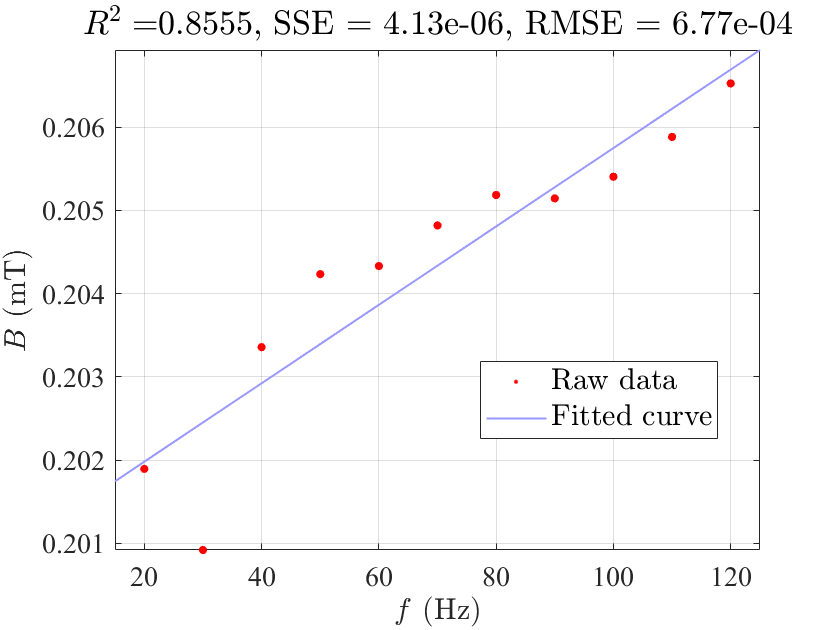

stc.label.x.String = '$f$ (Hz)';
stc.label.y.String = '$B$ (mT)';
%MyExport_pdf_docked

# 思考题

K_H = 363.6;
sigma_K_H = 0.8;
I_S = 1e-3;
sigma_I_S = 1e-5;
U_H = 0.0257;
simga_U_H = 1e-4;

sigma = sqrt( (I_S*U_H*sigma_K_H)^2 + (sigma_I_S*U_H*K_H)^2 + (I_S*simga_U_H*K_H)^2  )

sigma = 1.0236e-04

vpa(sigma*1000)

$$ans = 0.10235608727887171576220737279073$$

function data = PrintData(data)
    array2table(data)
end
